load train.mat;
load test.mat;

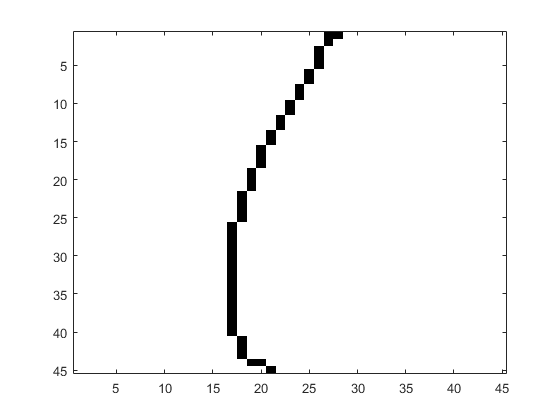

s = size(train_images{1});
for i=1:length(train_images)
    train_images{i} = reshape(logical(train_images{i} > 128), s(1)*s(2), []);
end
flat = double([train_images{:}]);
figure(); clf;
imagesc(reshape(flat(:, 1), 45, 45));
colormap gray;

train_data = flat;% - mean(mean(flat));

model = train_model(train_data', train_labels, 64);

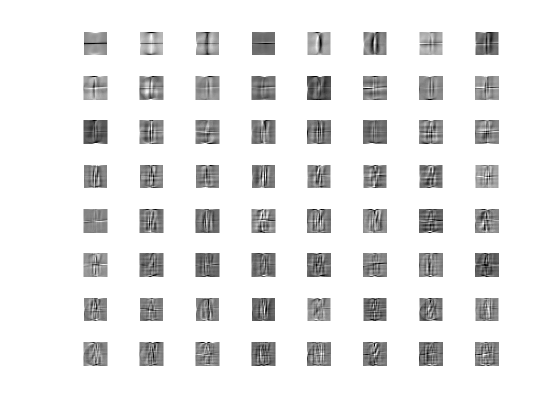

clf
subplot_size = ceil(sqrt(size(V, 2)));
for i = 1:size(V, 2)
    subplot(subplot_size, subplot_size, i);
    img_size = sqrt(size(V, 1));
    imagesc(reshape(V(:, i), [img_size img_size])); colormap('gray');
    axis equal;
    set(gca, 'visible', 'off');
end

V = model.eigenvectors;
save("model.mat", "model");

load model.mat;

%test_data = [img_load("test-data/3"); img_load("test-data/4");];
for i=1:length(test_images)
    test_images{i} = reshape(logical(test_images{i} > 128), s(1)*s(2), []);
end
flat_test = double([test_images{:}]);
test_data = flat_test;%- mean(mean(flat_test));

train_data_projected = V'*train_data;
test_data_projected = V'*test_data;

matches = knnsearch(train_data_projected', test_data_projected');

save("results.mat", "matches")

load results.mat;

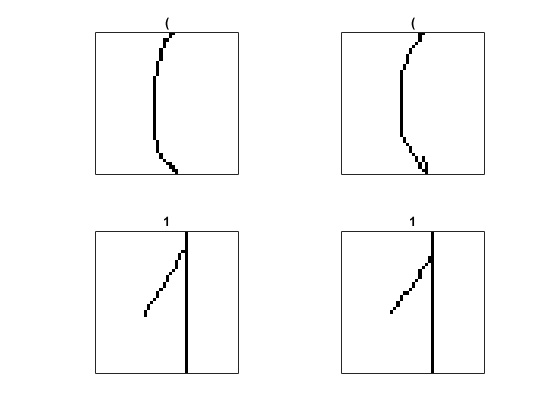

range = 1:10000:length(matches);
figure(); clf;
index = 1;
for i=range
    match = matches(i);
    img = train_data(:, match);
    img_size = sqrt(length(img));
    img = reshape(img, [img_size img_size]);
    
    subplot(length(range), 2, index * 2 - 1);
    imagesc(img); colormap('gray');
    axis equal; axis square;
    title(train_labels(match));
    set(gca,'xtick',[])
    set(gca,'ytick',[])
   
    subplot(length(range), 2, index * 2);
    test_img = reshape(test_data(:, i), img_size, img_size);
    imagesc(test_img);
    axis equal; axis square;
    title(test_labels(i));
    set(gca,'xtick',[])
    set(gca,'ytick',[])
    
    index = index + 1;
end

accuracy = mean([train_labels(matches) == test_labels])

accuracy = 0.8565

length(matches)

ans = 16459

%range = 1:10000:length(matches);
range = 1:length(matches);
figure(); clf;
index = 1;
for i=range
    match = matches(i);
    img = train_data(:, match);
    img_size = sqrt(length(img));
    
    test_img = test_data(:, i);

    index = index + 1;
    if isequal(test_img, img)
        %delete(test.Files{i});
        removed = removed + 1;
    end
end
removed

removed = 47